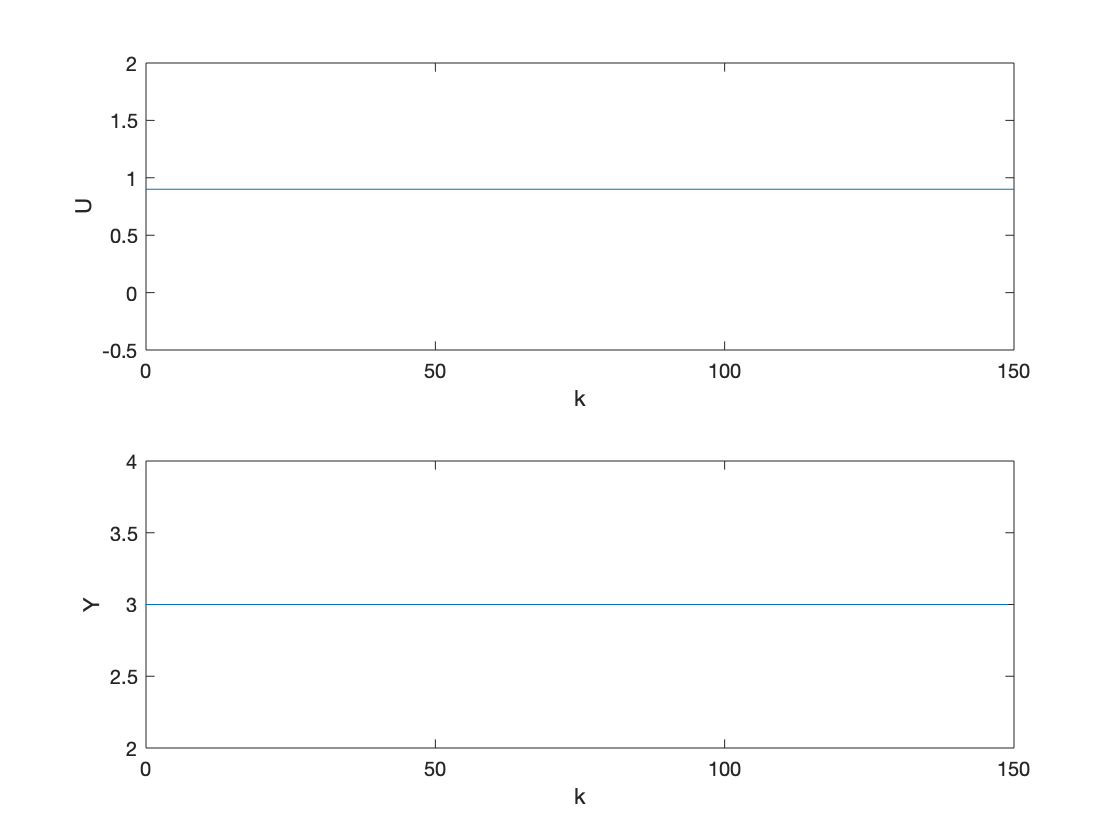

Upp = 0.9;
Vpp = 3;
Umin = 0.6;
Umax = 1.2;
Tp = 0.5;
imax = 150;
Y = zeros(1, imax);
U = zeros(1, imax+1);
Y(1) = Vpp;
Y(2) = Vpp;
U(1:imax+1) = Upp;
for i = 3:imax
    Y(i) = symulacja_obiektu2Y_p1(Upp, Upp, Y(i-1), Y(i-2));
end
subplot(2,1,1);
stairs(0:length(U)-1, U);
xlabel('k');
ylabel('U');
subplot(2,1,2);
stairs(0:length(Y)-1, Y);
xlabel('k');ylabel('Y');

2. 

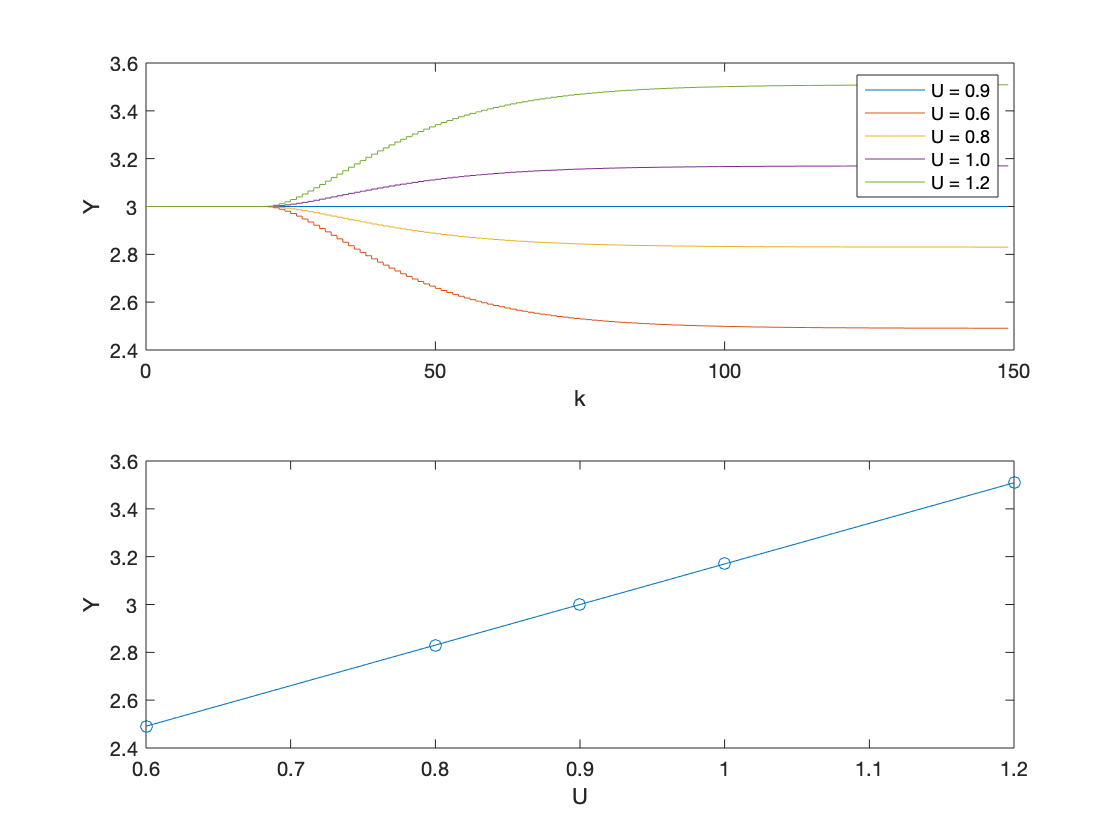

Yu = zeros(1,5);
Uu = [Upp, 0.6, 0.8, 1, 1.2];
U = zeros(1, imax);
U(1:11) = Upp;
Y(1:11) = Vpp;

for i = 1:5
    U(12:imax)= Uu(i);
    for k = 12:imax
        Y(k) = symulacja_obiektu2Y_p1(U(k-10), U(k-11), Y(k-1), Y(k-2));
    end
    
    Yu(i) = Y(imax);
    
%     subplot(2,1,1);
%     stairs(0:length(U)-1, U);
    
%     hold on;
%     subplot(2,1,2);
    subplot(2,1,1);
    stairs(0:length(Y)-1, Y);
    hold on;   
end
legend("U = 0.9", "U = 0.6", "U = 0.8", "U = 1.0", "U = 1.2")
xlabel("k")
ylabel("Y")
subplot(2,1,2);
plot(Uu, Yu, "o");
hold on
xlabel("U");
ylabel("Y");
lsline;
hold off


Kstat=(Yu(5)-Yu(1))/(Uu(5)-Uu(1))

Kstat = 1.6966


% 
% for i = 12:imax
%     Y(i) = symulacja_obiektu2Y_p1(U(i-10), U(i-11), Y(i-1), Y(i-2));
% end
% Yu(1) = Y(imax);
% stairs(Y)
% hold on
% for i = 12:imax
%     Y(i) = symulacja_obiektu2Y_p1(U(i-10), U(i-11), Y(i-1), Y(i-2));
% end
% Yu(2) = Y(imax);
% stairs(Y)
% 
% xlabel("k")
% ylabel("Y")
% hold on
% for i = 12:imax
%     Y(i) = symulacja_obiektu2Y_p1(U(i-10), U(i-11), Y(i-1), Y(i-2));
% end
% Yu(3) = Y(imax);
% stairs(Y)
% for i = 12:imax
%     Y(i) = symulacja_obiektu2Y_p1(U(i-10), U(i-11), Y(i-1), Y(i-2));
% end
% Yu(4) = Y(imax);
% stairs(Y)
% for i = 12:imax
%     Y(i) = symulacja_obiektu2Y_p1(U(i-10), U(i-11), Y(i-1), Y(i-2));
% end
% Yu(5) = Y(imax);
% stairs(Y)
% legend("U = 0.9", "U = 0.6", "U = 0.8", "U = 1.0", "U = 1.2")
% hold off
% 
% subplot(2,1,2)
% plot(Uu, Yu, "o");
% hold on
% xlabel("U");
% ylabel("Y");
% lsline;
% hold off

3. 